# Pattern search for PID controller

%0 initialisation and set up
    %0.0 plant transfer function     
        s = tf('s');
        G = 1/(s*(s^2+s+1));
    %0.1 desired cahracteristics
        rise_time=2

rise_time = 2

        settling_time=4

settling_time = 4

        peak_overshoot=30   %in percent copared tosteady state value

peak_overshoot = 30

        undershoot=10       %in percet compared to steady state value

undershoot = 10

    %0.2 Algorithim paramaters
        tolerance=1 %does nothing 

tolerance = 1

        weighting=[2,10,1,0.1,5]  %rise time,settling time, peak overshoot, steady state, undershoot

weighting =     2.0000   10.0000    1.0000    0.1000    5.0000


        num_tests=1               %no. times to run the algorithim 

num_tests = 1

        x_bound=10                %acceptable solution to stop re running 

x_bound = 10

        % options on the algorithim 
        K=0;
        x=inf;
        trial_values=[0.5582;0.003519;0.7934]

trial_values =     0.5582
    0.0035
    0.7934


%1 algorithim implementation 
    for i=1:num_tests
        [K_test,x_test]=PID_Best(G,rise_time,settling_time,peak_overshoot,undershoot,tolerance,weighting,trial_values);
        if x_test<x
            K=K_test;
            x=x_test;
        end
        if x<x_bound
            break
        end
    end

Optimization terminated: mesh size less than options.MeshTolerance.



%2 testing output solution 
    C=K(1)+K(2)/s+K(3)*s    %controller transfer function 

C =
 
  0.8637 s^2 + 0.5582 s + 0.005409
  --------------------------------
                 s
 
Continuous-time transfer function.



    H=feedback(C*G,1)       %closed loop transfer function 

H =
 
       0.8637 s^2 + 0.5582 s + 0.005409
  -------------------------------------------
  s^4 + s^3 + 1.864 s^2 + 0.5582 s + 0.005409
 
Continuous-time transfer function.



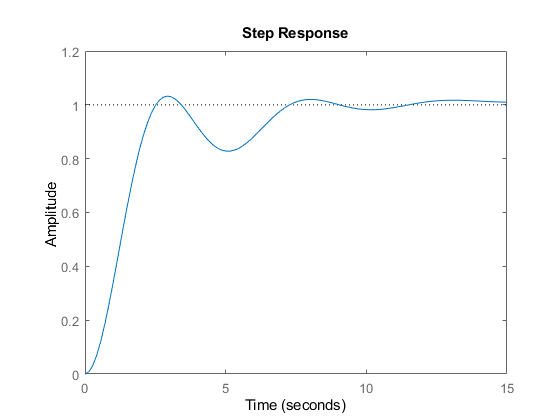

    step(H)                 %step response

    stepinfo(H)             %step paramaters

ans = struct with fields:
        RiseTime: 1.6151
    SettlingTime: 6.9801
     SettlingMin: 0.8280
     SettlingMax: 1.0323
       Overshoot: 3.2322
      Undershoot: 0
            Peak: 1.0323
        PeakTime: 2.9321


    %final fitness value
    fitness=pidtest(G,rise_time,settling_time,peak_overshoot,undershoot,tolerance,weighting,K)

fitness = 7.4604e+04

function [K,x]=PID_Best(G,rise_time,settling_time,peak_overshoot,undershoot,tolerance,weighting,trial_values)

fitness_function=@(K)pidtest(G,rise_time,settling_time,peak_overshoot,undershoot,tolerance,weighting,K);

[K,x] = patternsearch(fitness_function,trial_values,-1*eye(3),zeros(3,1));
end

function fitness=pidtest(G,rise_time,settling_time,peak_overshoot,undershoot,tolerance,weighting,K)
    s=tf('s');
    C=K(1)+K(2)/s+K(3)*s;
    H=feedback(C*G,1);
    info=stepinfo(H);
    errors=zeros(size(weighting));
    errors(1)=normalize(info.RiseTime-rise_time);
    errors(2)=normalize(info.SettlingTime-settling_time);
    y_ss=FVT(H);
    errors(4)=normalize(abs(y_ss-1));
    errors(3)=normalize(max(info.Overshoot, 100*(info.SettlingMax/y_ss-1))-peak_overshoot);
    errors(5)=normalize(max(info.Undershoot,(1-info.SettlingMin/y_ss)*100)-undershoot);
    fitness=0;
    
    for i=1:length(weighting)
        fitness=fitness+errors(i)^weighting(i);    
    end
    
    function output=normalize(input)
        output=heaviside(input)*input;
    end
    
    function y_end=FVT(H)
        y_end=evalfr(H,0);
    end
end
